# **CA#3 **

# Sogol Goodarzi 

# 810198467

# **Part(1): Generate and Transfer Symbols with 4-PAM Modulation**

## 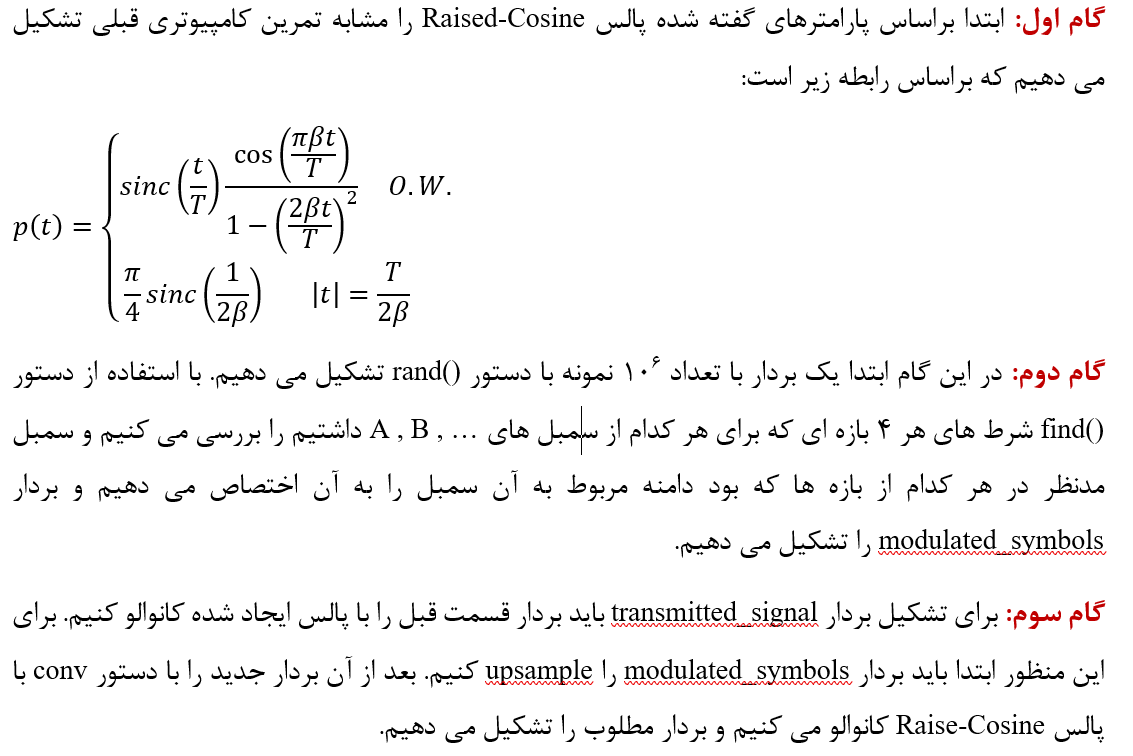

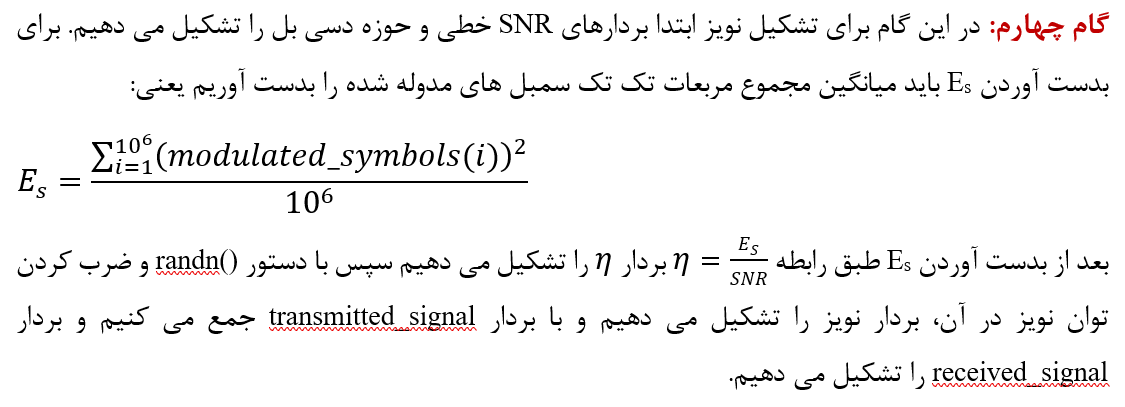

clear;
beta = 0;
Ts = 1;
Fs = 10;
delta_t = Ts/Fs;
L = Fs*Ts;
t = (-6*L:6*L)/Fs;
%--- Raised-Cosine Pulse Generation ---
pulse = sinc(t/Ts).*(cos(pi*beta*t/Ts)./(1-(2*beta*t/Ts).^2));
pulse(find(t==abs(Ts/(2*beta)))) = pi/4*sinc(1/(2*beta));
% ---  Transmitted Signal Generation ---
N = 1e6;
Samples = rand(1,N);
modulated_symbols = Samples;
modulated_symbols(find(Samples>=0 & Samples<0.1)) = -3;
modulated_symbols(find(Samples>=0.1 & Samples<0.5)) = -1;
modulated_symbols(find(Samples>=0.5 & Samples<0.9)) = 1;
modulated_symbols(find(Samples>=0.9 & Samples<1)) = 3;
temp0 = upsample(modulated_symbols,L);
temp0 = temp0(1:end-(L-1));
transmitted_signal = conv(temp0,pulse);
% --- AWGN Channel Modeling ---
SNR_dB = 0:10;
SNR = 10.^(SNR_dB./10);
Es = sum(modulated_symbols.^2)/N

Es = 2.5981

etha = Es./SNR;
Noise = (sqrt(etha./2))'*randn([1,length(transmitted_signal)]);
received_signal = transmitted_signal + Noise;

# **Part(2): Symbol Revelation with MAP and ML**

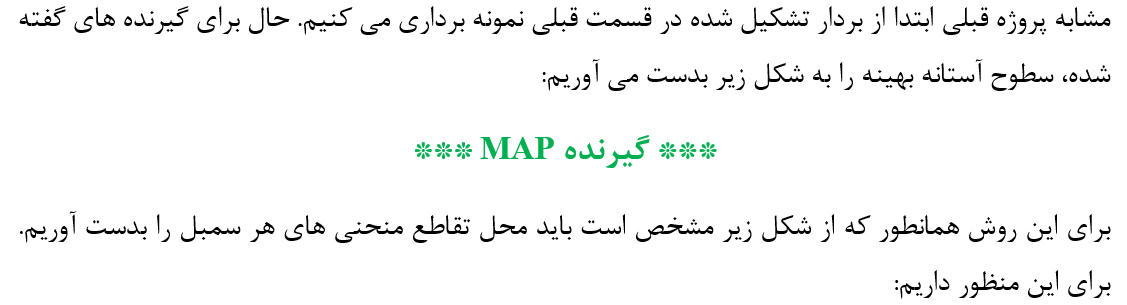

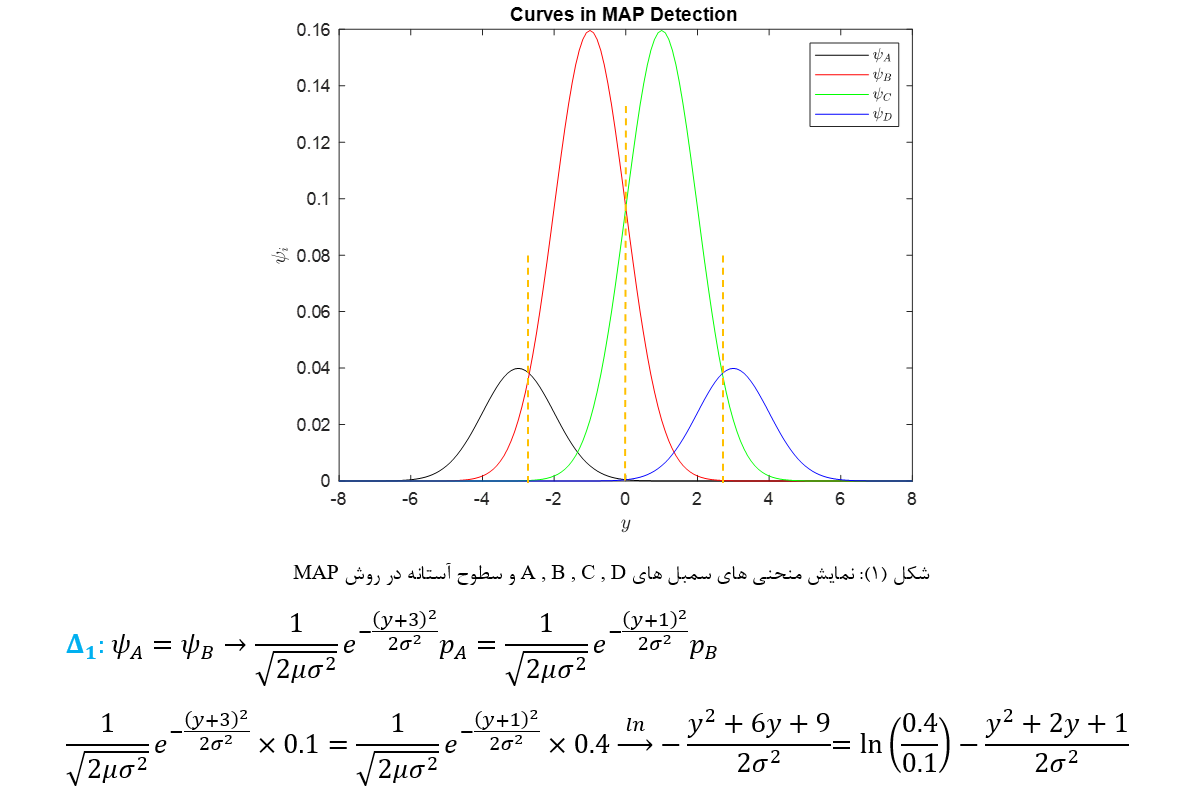

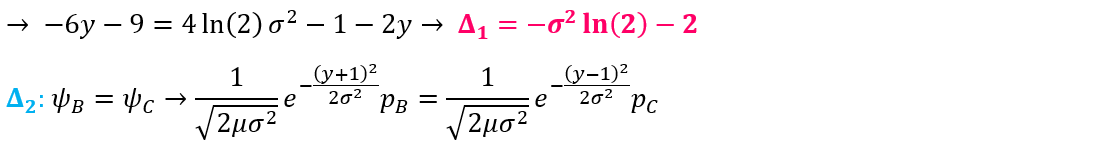

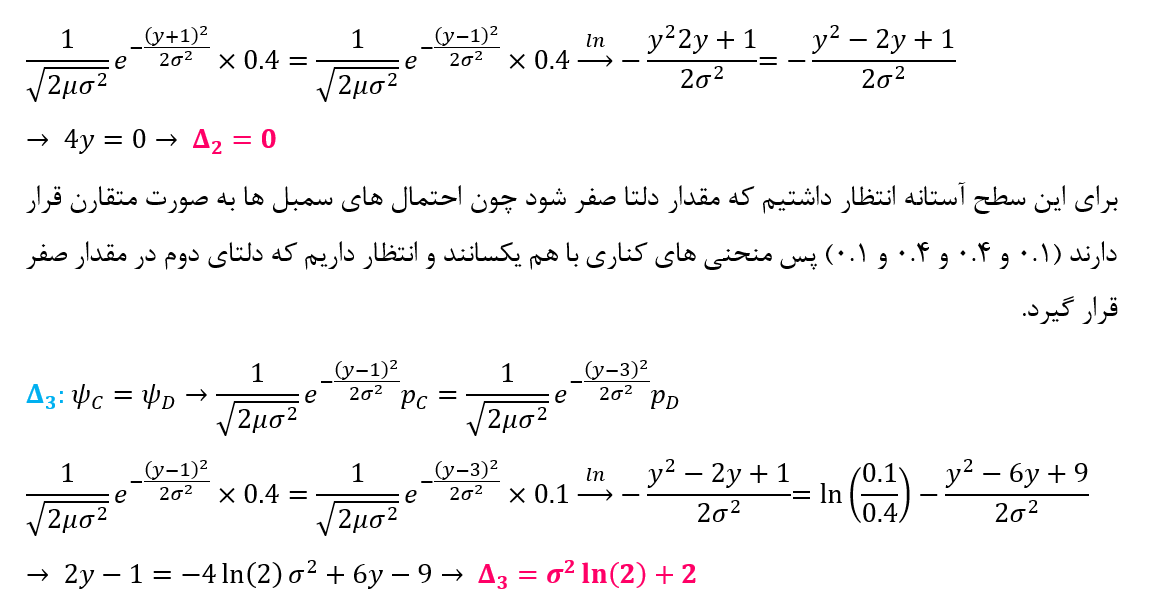

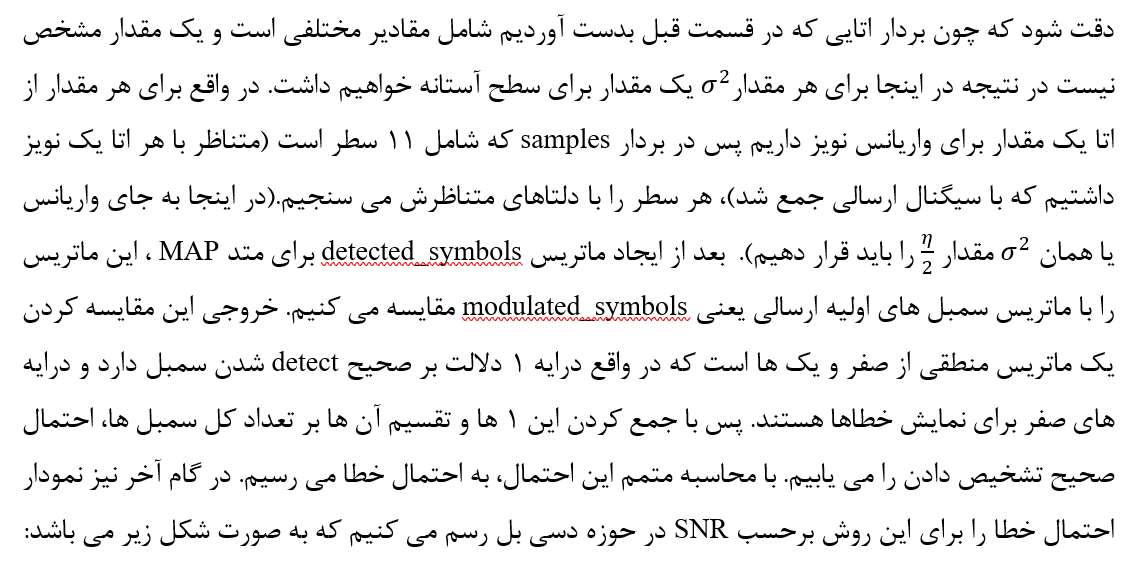

T_sampling = 6*L+1:L:(N+6-1)*L+1;
samples = received_signal(:,T_sampling);

## MAP Method:

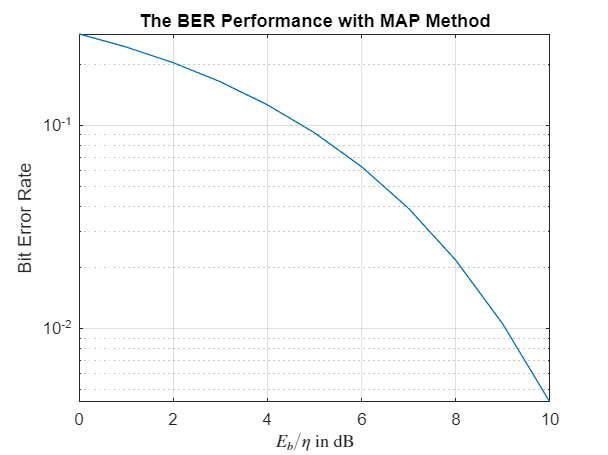

Delta1 = -(etha./2.*log(2)+2);
Delta2(1:11) = 0;
Delta3 = etha./2.*log(2)+2;
for i=1:length(etha)
    detected_symbols_MAP(i,find(samples(i,:)<Delta1(i))) = -3;
    detected_symbols_MAP(i,find(samples(i,:)>Delta1(i) & samples(i,:)<Delta2(i))) = -1;
    detected_symbols_MAP(i,find(samples(i,:)>Delta2(i) & samples(i,:)<Delta3(i))) = 1;
    detected_symbols_MAP(i,find(samples(i,:)>Delta3(i))) = 3;
end
comparison_vec = detected_symbols_MAP == modulated_symbols;
pe_MAP = 1-sum(comparison_vec,2)./length(samples);
semilogy(SNR_dB,pe_MAP);
grid on
xlabel("$E_b/\eta$ in dB",'Interpreter','latex');
ylabel("Bit Error Rate");
title("The BER Performance with MAP Method");

## 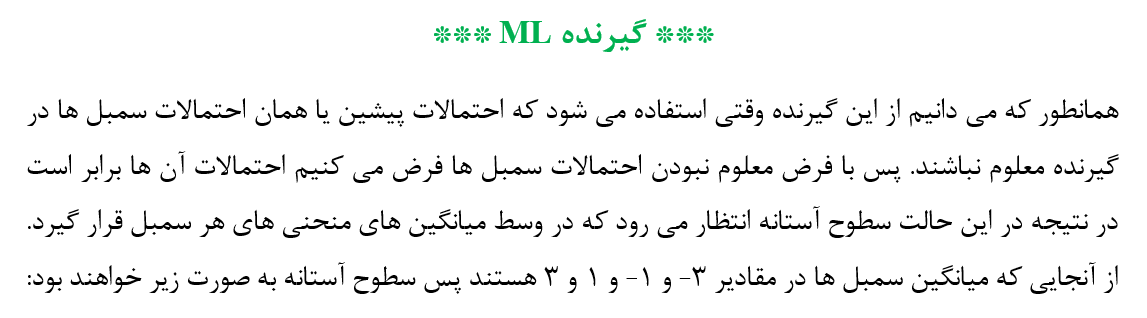

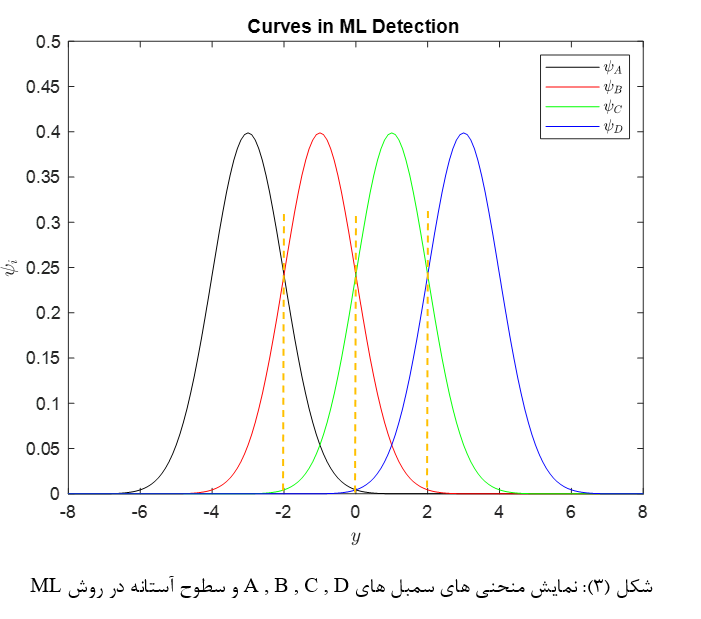

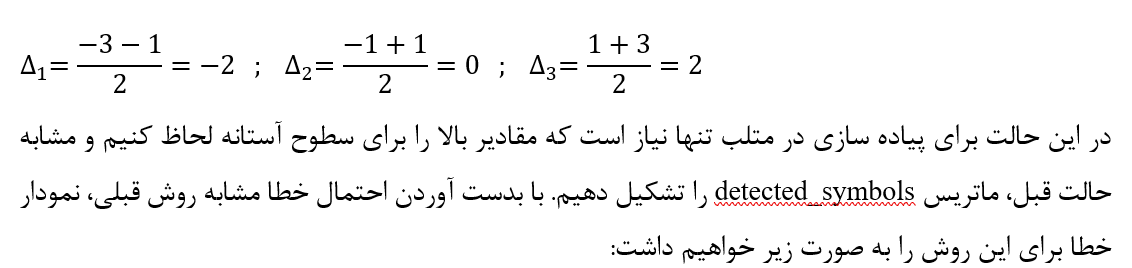

## ML Method:

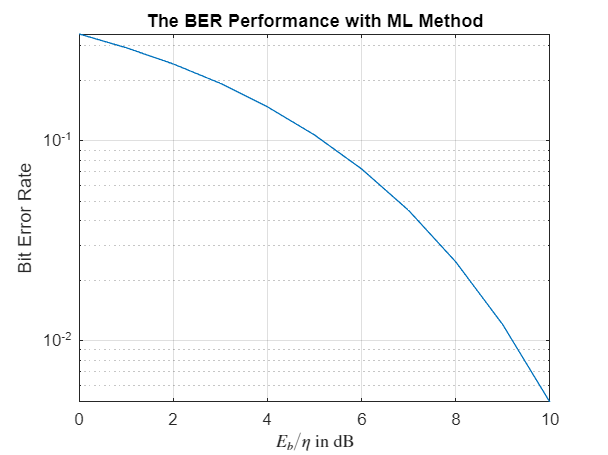

Delta1 = -2;
Delta2 = 0;
Delta3 = 2;
for i=1:length(etha)
    detected_symbols_ML(i,find(samples(i,:)<Delta1)) = -3;
    detected_symbols_ML(i,find(samples(i,:)>Delta1 & samples(i,:)<Delta2)) = -1;
    detected_symbols_ML(i,find(samples(i,:)>Delta2 & samples(i,:)<Delta3)) = 1;
    detected_symbols_ML(i,find(samples(i,:)>Delta3)) = 3;
end
comparison_vec = detected_symbols_ML == modulated_symbols;
pe_ML = 1-sum(comparison_vec,2)./length(samples);
semilogy(SNR_dB,pe_ML);
grid on
xlabel("$E_b/\eta$ in dB",'Interpreter','latex');
ylabel("Bit Error Rate");
title("The BER Performance with ML Method");

## 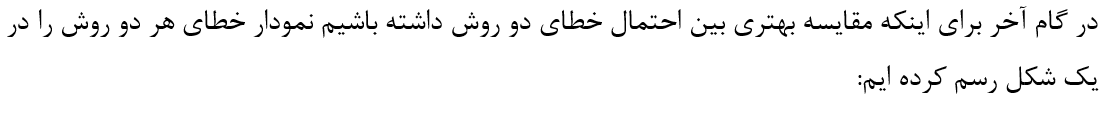

## Comparing the errors:

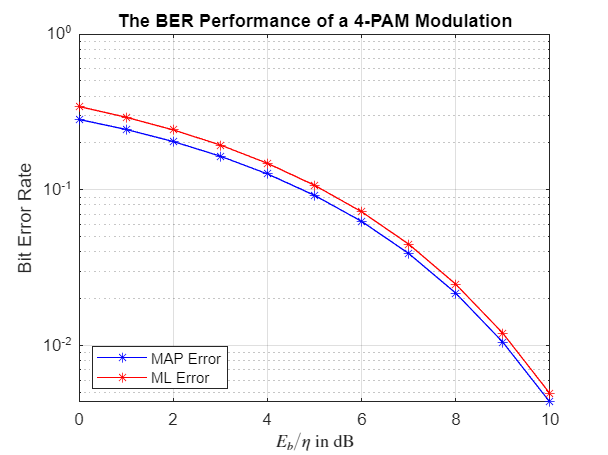

semilogy(SNR_dB,pe_MAP,'*b-');
grid on
hold on 
semilogy(SNR_dB,pe_ML,'*r-');
legend("MAP Error","ML Error",'Location','southwest');
xlabel("$E_b/\eta$ in dB",'Interpreter','latex');
ylabel("Bit Error Rate");
title("The BER Performance of a 4-PAM Modulation");
hold off